## FA3 strain

modelName = 'FA234';
open_system(modelName)
set_param(modelName + "/Manual Switch1",'sw','1')
set_param(modelName + "/Manual Switch2",'sw','1')
set_param(modelName + "/Manual Switch3",'sw','1')
set_param(modelName + "/Model selection (manual)",'Value','2') % FA4 model

p = sdo.getParameterFromModel(modelName,{'IPTG','addTime','arabi'});

% IPTG
p(1).Value = 100;
p(1).Minimum = 0;
p(1).Maximum = 1000;
p(1).Scale = 1000;
p(1).Free = 1;

% Arabinose adding time
p(2).Value = 0;
p(2).Minimum = 0;
p(2).Maximum = 25;
p(2).Scale = 25;
p(2).Free = 1;

% Arabinose concentration
p(3).Value = 0.5;
p(3).Minimum = 0;
p(3).Maximum = 1;
p(3).Scale = 1;
p(3).Free = 1;

options = sdo.OptimizeOptions;
options.Method = 'fmincon';

Exp = sdo.Experiment(modelName);
Exp = setEstimatedValues(Exp,p);

FFASignal = Simulink.SimulationData.Signal;
FFASignal.Name = 'Fatty acid';
FFASignal.BlockPath = modelName + "/GainFA";
FFASignal.PortType = 'outport';
FFASignal.PortIndex = 1;
FFASignal.Values = timeseries((1:25)',(1:25)'); % What does this mean?

Exp.OutputData = FFASignal; % add the signal object to the experiment

Simulator = createSimulator(Exp);
estFcn = @(p) optInputObjective(p,Simulator,Exp);

val = optInputObjective(p,Simulator,Exp);
val.F

ans = -1.2162

tic
[optInput,optInputInfo] = sdo.optimize(estFcn,p,options)


 最適化開始時間 15-Nov-2023 22:50:15

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      6     -1.21616            0
    1     16     -1.40429            0        0.492         3.12
    2     22     -1.58614            0        0.614         1.78
    3     28     -1.84452            0        0.356         2.76
    4     34     -1.86576            0        0.139         1.75
    5     40     -2.02851            0        0.111         1.26
    6     47     -2.09382            0        0.364         1.92
    7     54     -2.10689            0        0.127         3.55
    8     60     -2.14752            0        0.114         1.57
    9     66     -2.19413            0        0.112         1.12
   10     72     -2.20028            0       0.0352        0.316
   11     77     -2.20028            0     0.000869        0.316
局所的最小値の可能性があります。制約が満たされました。

現在のステップ サイズがステップ サイズの許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされ

optInputInfo = フィールドをもつ struct :
               F: -2.2003
       Gradients: [1×1 struct]
        exitflag: 2
      iterations: 11
    SolverOutput: [1×1 struct]
           Stats: [1×1 struct]


toc

経過時間は 68.006319 秒です。


maxFFA_FA4 = -optInputInfo.SolverOutput.fval;

spv_length = 26;
setPointValuesIPTG = logspace(0,3,spv_length); % 1-1000 uM IPTG
setPointValuesAddTime = linspace(0,25,spv_length); % 0-25 h arabinose adding time

k = 1;
for i = 1:1:spv_length
    for j = 1:1:spv_length
        in(k) = Simulink.SimulationInput(modelName);
        in(k) = in(k).setBlockParameter(modelName + "/To optimize input",...
        'Value',num2str(setPointValuesIPTG(i)));
        in(k) = in(k).setBlockParameter(modelName + "/Arabinose",...
            'Time',num2str(setPointValuesAddTime(j)));
        k = k + 1;
    end
end

save('optInput_FA4','optInput')
sdo.setValueInModel(modelName,optInput);

## Plot the convex curve

out_FA4 = sim(in,'ShowSimulationManager','on','ShowProgress','on')

[15-Nov-2023 22:52:41] シミュレーションの実行中...
[15-Nov-2023 22:52:42] シミュレーション実行 1/676 が完了
[15-Nov-2023 22:52:43] シミュレーション実行 2/676 が完了
[15-Nov-2023 22:52:44] シミュレーション実行 3/676 が完了
[15-Nov-2023 22:52:44] シミュレーション実行 4/676 が完了
[15-Nov-2023 22:52:45] シミュレーション実行 5/676 が完了
[15-Nov-2023 22:52:45] シミュレーション実行 6/676 が完了
[15-Nov-2023 22:52:46] シミュレーション実行 7/676 が完了
[15-Nov-2023 22:52:47] シミュレーション実行 8/676 が完了
[15-Nov-2023 22:52:48] シミュレーション実行 9/676 が完了
[15-Nov-2023 22:52:48] シミュレーション実行 10/676 が完了
[15-Nov-2023 22:52:49] シミュレーション実行 11/676 が完了
[15-Nov-2023 22:52:50] シミュレーション実行 12/676 が完了
[15-Nov-2023 22:52:50] シミュレーション実行 13/676 が完了
[15-Nov-2023 22:52:51] シミュレーション実行 14/676 が完了
[15-Nov-2023 22:52:52] シミュレーション実行 15/676 が完了
[15-Nov-2023 22:52:52] シミュレーション実行 16/676 が完了
[15-Nov-2023 22:52:53] シミュレーション実行 17/676 が完了
[15-Nov-2023 22:52:54] シミュレーション実行 18/676 が完了
[15-Nov-2023 22:52:54] シミュレーション実行 19/676 が完了
[15-Nov-2023 22:52:55] シミュレーション実行 20/676 が完了
[15-Nov-2023 22:52:56] シミュレーション実行 21/676 が完了
[15-Nov-2023 22:52:56] シミ

out_FA4 = 1x676 Simulink.SimulationOutput 配列



FFA_end_FA4 = zeros(spv_length^2,1);
for simIdx = 1:spv_length^2
    FFA_end_FA4(simIdx,1) = out_FA4(simIdx).logsout{1}.Values.Data(end);
end

FFA_end_FA4 = reshape(FFA_end_FA4,[spv_length,spv_length]);
[X,Y] = meshgrid(logspace(0,3,spv_length),linspace(0,25,spv_length));

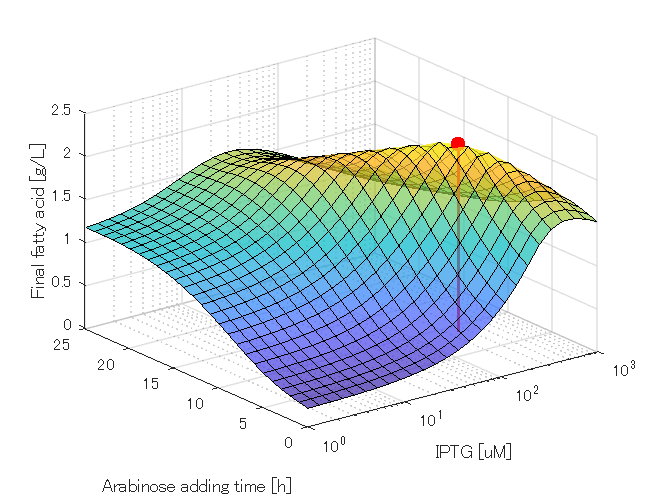

figure('Position', [100 100 480 360]);
surf(X,Y,FFA_end_FA4);
xlim([1 1000])
ylim([0 25])
zlim([0 2.5])
xlabel('IPTG [uM]')
ylabel('Arabinose adding time [h]')
zlabel('Final fatty acid [g/L]')
set(gca,'xscale','log')
alpha(0.7)
% clim([0 2.5])
hold on
stem3(optInput(1).Value,optInput(2).Value,maxFFA_FA4,'ro','MarkerFaceColor','red','LineWidth',2)
hold off